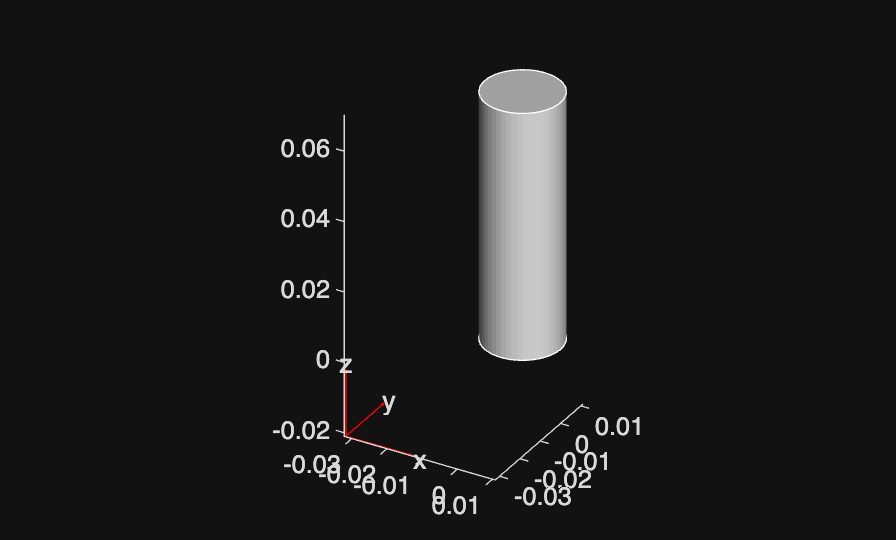

% dimensions
D=0.02155;
r=D/2;
h=0.070155;
m=0.07;
V=pi*r^2*h;
SA=2*pi*(r^2)+2*pi*(r^2)*h;
rho = m/V;   % density, kg/m^3
% specs
V_nominal=3.6;
R_i=0.015;
%test conditions
I=10;    %choose a discharge current, A
T_ambient=25+273.15;
T_0=T_ambient;
h_conv=20;   %convective heat transfer coefficient (cfd?) (???)
% thermo
C_p=1040;   % specific heat, J/kg*K (???)
k_r=0.9;  %thermal conductivity (???)
k_theta=k_r;    %angle symmetry
k_z=24.2;    % (???)
q=(I^2)*(R_i)/V; %volumetric heat generation, W/m^3

%pde, transient thermal model -> rhoC_p(partialT/partialt)=grad dot
%(kgradT) + q

thermalmodel = createpde('thermal','transient');
thermalmodel.Geometry = multicylinder(r, h);
figure; pdegplot(thermalmodel);

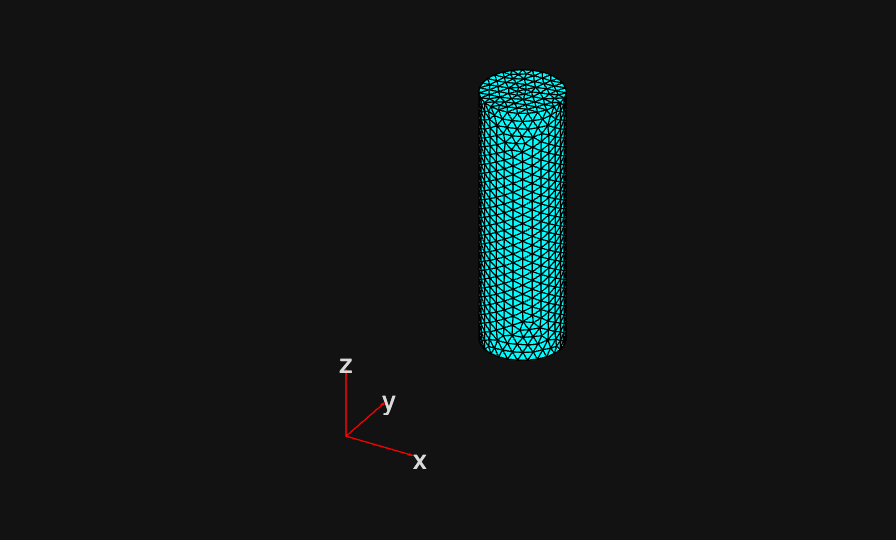

allfaces=1:thermalmodel.Geometry.NumFaces;
hmax=0.0025;
generateMesh(thermalmodel, 'Hmax',hmax);
figure; pdemesh(thermalmodel)

k=[k_r;k_theta;k_z];
% Define thermal properties
thermalProperties(thermalmodel, 'ThermalConductivity',k,'MassDensity',q,'SpecificHeat',C_p);
internalHeatSource(thermalmodel, q);
% define boundary/initial conditions
thermalBC(thermalmodel, "Face",allfaces,"ConvectionCoefficient",h_conv,"AmbientTemperature",T_ambient);
thermalIC(thermalmodel,T_0);
% Solve the transient thermal model
tlist = 0:5:3600; % time vector
result = solve(thermalmodel, tlist);
T_f=result.Temperature(:,end);


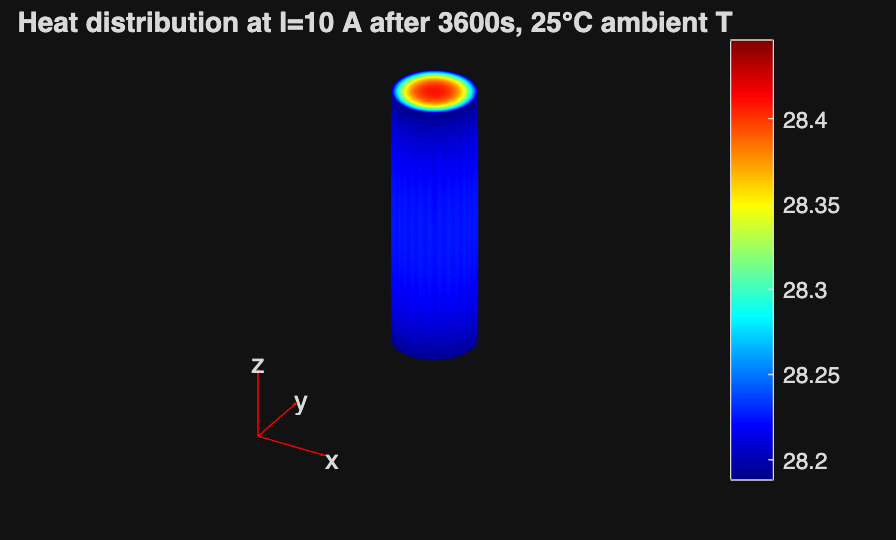

%visualize
figure;
pdeplot3D(thermalmodel,"ColorMapData",T_f-273.15)
title(sprintf("Heat distribution at I=10 A after 3600s, 25°C ambient T"))
colorbar;

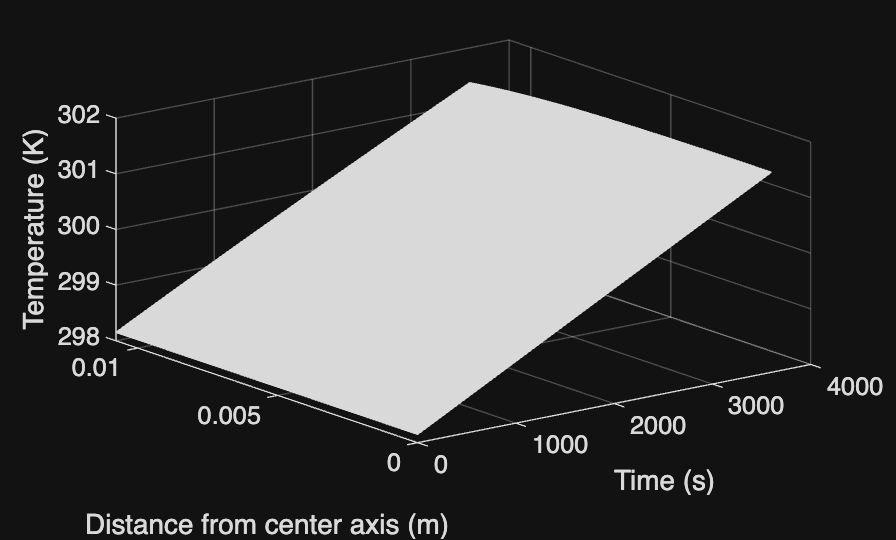

%graph
d_x=linspace(0,r,100);
d_y=zeros(size(linspace(0,r,100)));
d_z=ones(size(linspace(0,r,100)))*(h/2);

T_radial=zeros(100, length(tlist));
for i=1:length(tlist)
    T_radial(:,i) = interpolateTemperature(result, d_x, d_y, d_z, i);
end

figure;
surf(tlist,d_x,T_radial)
xlabel(sprintf("Time (s)"))
ylabel(sprintf("Distance from center axis (m)"))
zlabel(sprintf("Temperature (K)"))